close all;
clear; clc;
format compact;

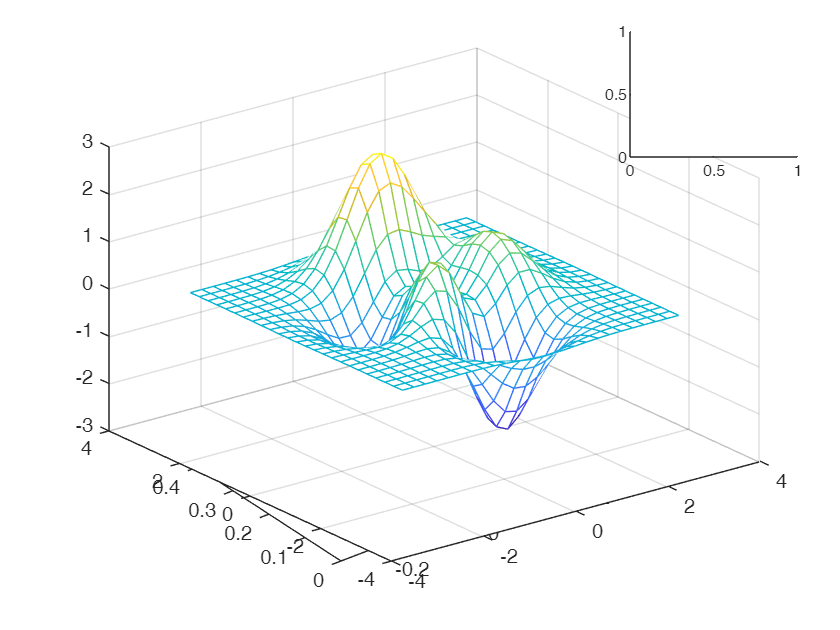

Unrecognized function or variable 'plotframe'.
Error in plotHomogFrames (line 41)
plotframe( Parent=axIcon, LabelBasis=true )

theta = 0;
d1 = 1;
theta2 = -pi/2;

figure;
for t = 1:0.1:5
    if t < 2
        theta = t * 0.6;
    
        DH = [  pi/2 + theta,  0, 0,  pi/2 ;
            0, d1, 0,  -pi/2;
            -pi/2 - 0, 0, 0.75, 0];

    elseif t<4
        d1 = 1+(t-2) * 0.5;
    
        DH = [  pi/2 + theta,  0, 0,  pi/2 ;
            0, d1, 0,  -pi/2;
            -pi/2 - 0, 0, 0.75, 0];
    else
        theta1 = -pi/2 + (t-4)*0.75;
        DH = [  pi/2 + theta,  0, 0,  pi/2 ;
            0, d1, 0,  -pi/2;
            theta1, 0, 0.75, 0];
    end
 
    homogTF = dhTransforms(DH);

    clf;

    plotHomogFrames(homogTF, 'scale', 0.5, 'arrowstyle', 'line');
    xlim([-1, 2.5]); ylim([0, 3.5]); zlim([0, 0.5]);
drawnow;
%     pause(0.0001);
end

dhparams = [0   	pi/2	0   	0;
            0.4318	0       0       0
            0.0203	-pi/2	0.15005	0;
            0   	pi/2	0.4318	0;
            0       -pi/2	0   	0;
            0       0       0       0];

robot = rigidBodyTree;

bodies = cell(6,1);
joints = cell(6,1);
for i = 1:6
    bodies{i} = rigidBody(['body' num2str(i)]);
    joints{i} = rigidBodyJoint(['jnt' num2str(i)],"revolute");
    setFixedTransform(joints{i},dhparams(i,:),"dh");
    bodies{i}.Joint = joints{i};
    if i == 1 % Add first body to base
        addBody(robot,bodies{i},"base")
    else % Add current body to previous body by name
        addBody(robot,bodies{i},bodies{i-1}.Name)
    end
end

showdetails(robot)

--------------------
Robot: (6 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   body2(2)  
   2        body2         jnt2     revolute            body1(1)   body3(3)  
   3        body3         jnt3     revolute            body2(2)   body4(4)  
   4        body4         jnt4     revolute            body3(3)   body5(5)  
   5        body5         jnt5     revolute            body4(4)   body6(6)  
   6        body6         jnt6     revolute            body5(5)   
--------------------


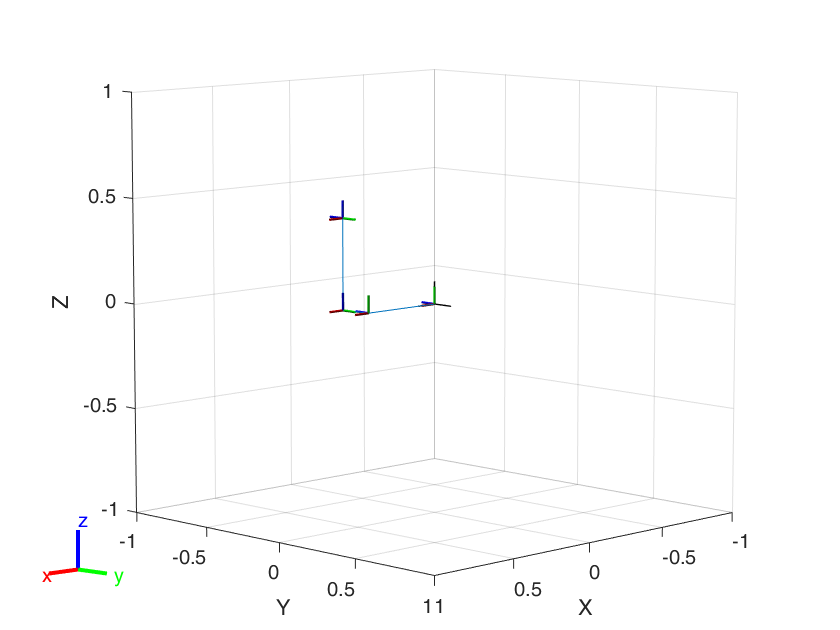

figure(Name="PUMA Robot Model")
show(robot);

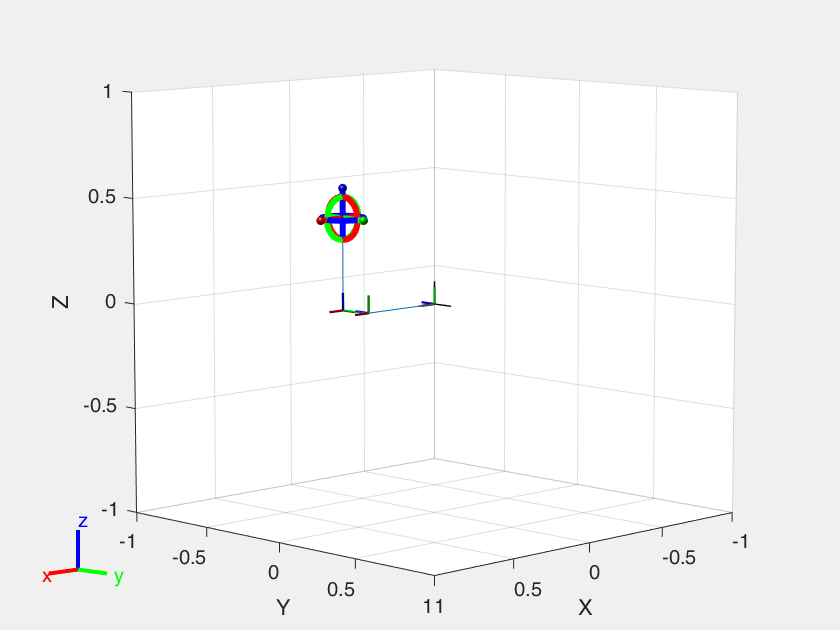

figure(Name="Interactive GUI")
gui = interactiveRigidBodyTree(robot,MarkerScaleFactor=0.5);